# Analisi Algoritmo di Bisezione 

In questa documentazione si mostreranno i casi di test relativi all'algoritmo di bisezione.

# Test di accuratezza

Il  test di accuratezza determina quanto la soluzione approssimata trovata attraverso il metodo di bisezione si avvicina alla soluzione dell'algoritmo fzero(). Quest'ultimo è il migliore algoritmo utilizzato per ffff lo zero in Matlab. Ai fini del calcolo dell' accuratezza è stata implementata la funzione CalcoloAccuratezza() . Essa calcola l'errore relativo tra le soluzioni restituite dai due algoritmi al medesimo problema. Una breve documentazione e l'implementazione della funzione è disponibile: 

doc CalcoloAccuratezza

## **Esempio**

Calcolare lo zero  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.

`Command line Matlab`

f = @(x)(2-exp(-x)-sqrt(x));
x0 = [0 4];

CalcoloAccuratezza(f,x0,1e-10);

Undefined function 'CalcoloAccuratezza' for input arguments of type 'function_handle'.

CalcoloAccuratezza(f,x0,1e-11)
CalcoloAccuratezza(f,x0,1e-12)
CalcoloAccuratezza(f,x0,1e-13)
CalcoloAccuratezza(f,x0,1e-14)
CalcoloAccuratezza(f,x0,1e-15)
CalcoloAccuratezza(f,x0,eps)

`Esecuzione da interfaccia grafica`

MainGUI();

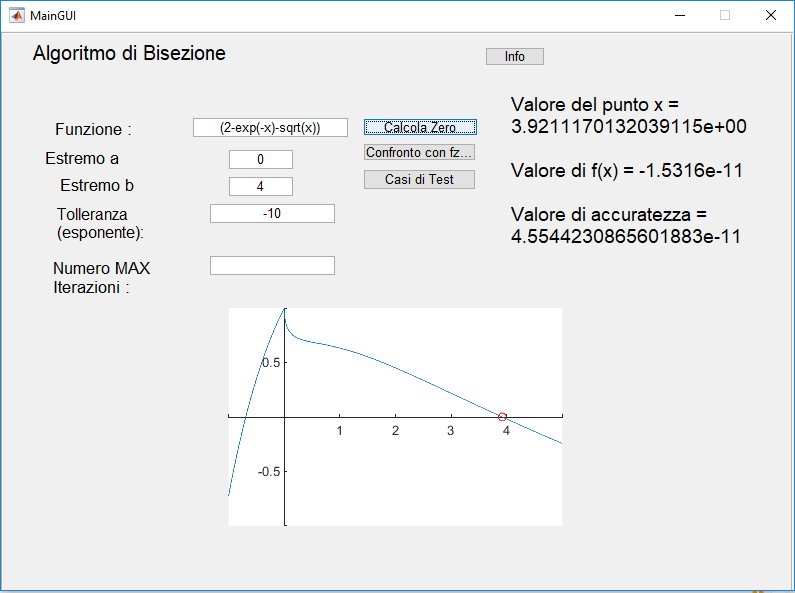

# Valutazione Performance

Si è implementata una funzione che crea un grafico di confronto tra i due algoritmi sopra citati. Si è calcolata la performance confrontando il numero di iterazioni necessarie all'algoritmo di Bisezione con quelle necessarie alla funzione fzero() considerata la tolleranza richiesta. 

## **Esempio**

Calcola la performance dell'algoritmo di bisezione quando è in input f=  di $2-e^{-x} \;-\sqrt{x}$ nell'intervallo $\left\lbrack 0,4\right\rbrack$ al variare della tolleranza TOL inserita dall'utente supponendo NMAX di default.L La funzione restituirà un grafico di confronto tra i due approcci.

`Command line Matlab`

f = @(x) (2-exp(-x)-sqrt(x));%funzione handle
xo = [0 4];
TOL=[10.^-1 10.^-2 10.^-3  10.^-4 10.^-5 10.^-6 10.^-7 10.^-8 10.^-9 10.^-10 10.^-12 10.^-13 10.^-14 eps];
Valuta_Performance(f,x0,TOL);

`Esecuzione da interfaccia grafica`

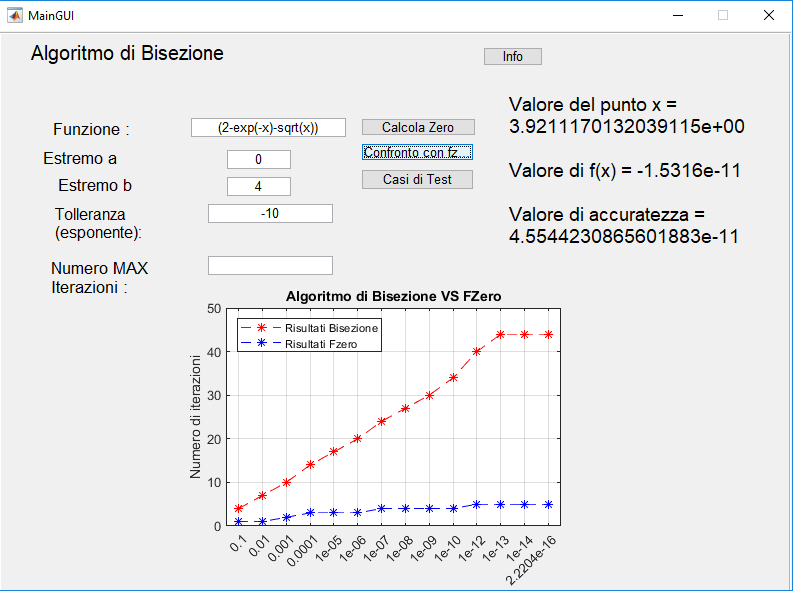

Come si nota dal grafico il numero di iterazioni richieste dalla funzione fzero() è minore rispetto a quelle della funzione algoritmo_di_bisezione() per ogni valore di TOL. Si può osservare che la differenza tra i due approcci è tanto più marcata quanto più si cerca una risoluzione migliore diminuendo la tolleranza.

# Test di robustezza

Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 15 ,implementati in una classe definita dal matlab matlab.unittest.TestCase inserendo al suo interno un costruttore che riceve i parametri della funzione che la test suite deve testare. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test saranno mostrate successivamente.

Il sistema esegue in automatico i test, riportando in tabella i test eseguiti con successo e quelli senza successo. 

Di seguito seguono i casi di test più rilevanti che sono stati effettuati. La funzione da testare sarà generata da linea di comando e passata alla test suite.

## Test case 4

 Verifica l'errore nel caso in cui il primo estremo o il secondo estremo dell'intervallo inserito non è un numero.

##     **Passed Test**

## Input

- f: valido

- x0: non valido

- TOL:valido,opzionale

- NMAX:valido,opzionale

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),['a' 4]);
result1 = run(test,'TestCase1');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido,opzionale

- NMAX:valido,opzionale.

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),[0 4]);
result1 = run(test,'TestCase4');
table(result1)

## Test case 3

 Verifica l'errore nel caso in cui entrambi gli  estremi dell'intervallo x0  siano vuoti.

## **Passed Test**

## Input

- f: valido

- x0: non valido

- TOL:valido

- NMAX:valido,opzionale.

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase3');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase3');
table(result1)

## Test case 6

 Verifica l'errore nel caso in cui entrambi i valori dell'intervallo x0 siano uguali.

## **Passed Test**

## Input

- f: valido

- x0: non valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase6');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase6');
table(result1)

## Test case 7

Verifica l'errore nel caso in cui non è soddisfatto il teorema degli zeri.

## **Passed Test**

## Input

- f: valido

- x0: non valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase7');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase7');
table(result1)

## Test case 8

Verifica che la tolleranza sia stata inserita o meno dall'utente.

## **Passed Test**

## Input

- f: valido

- x0: valido

- TOL: non valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase8');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase8');
table(result1)

## Test case 9

Si verifica se la tolleranza inserita è minore di eps.

## **Passed Test**

## Input

- f: valido

- x0: valido

- TOL: non valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase9');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase9');
table(result1)

## Test case 17

Verifica se l'accuratezza è adeguata  a partire da una determinata tolleranza TOL.

## **Passed Test**

## Input

- f: valido

- x0:valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase17');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase9');
table(result1)

## Test case 11

Verifica se il valore di NMAX  non è numerico, scalare,infinito oppure NaN.

## **Passed Test**

## Input

- f: valido

- x0:valido

- TOL:valido

- NMAX: non valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase11');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

- NMAX:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase11');
table(result1)

## Caso di test 13                                                                                                                   

Verifica se il valore di NMAX è minore o uguale a 2.

## **Passed Test**

## Input

- f: valido

- x0:valido

- TOL:valido

- NMAX:non valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase13');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

- NMAX:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase13');
table(result1)

## Caso di test 15                                                                                                                      

 Verifica se si è superato il numero massimo di iterazioniper determinare l'uscita. Non sarà trovato lo zero.

## **Passed Test**

## Input

- f: valido

- x0:valido

- TOL:valido

- NMAX:valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase15');
table(result1)

## **Failed Test**

**Input**

- f: valido

- x0:valido

- TOL:valido

- NMAX: valido

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test,'TestCase15');
table(result1)

##    Esecuzione intera test suite

Supponendo di considerare un input corretto che non restituisca nessun caso di errore:

test=exec_tests(@(x) (2-exp(-x)-sqrt(x)),x0,TOL,NMAX);
result1 = run(test);
table(result1);


Possiamo invece verificare che ogni condizione di warning o errore sia verificata  non assegnando un unico input per un intera test_suite ma immettendo i parametri direttamente dai singoli test case.

## Riferimenti                                                                                                                  

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autori                                                                                                                          

** Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936**